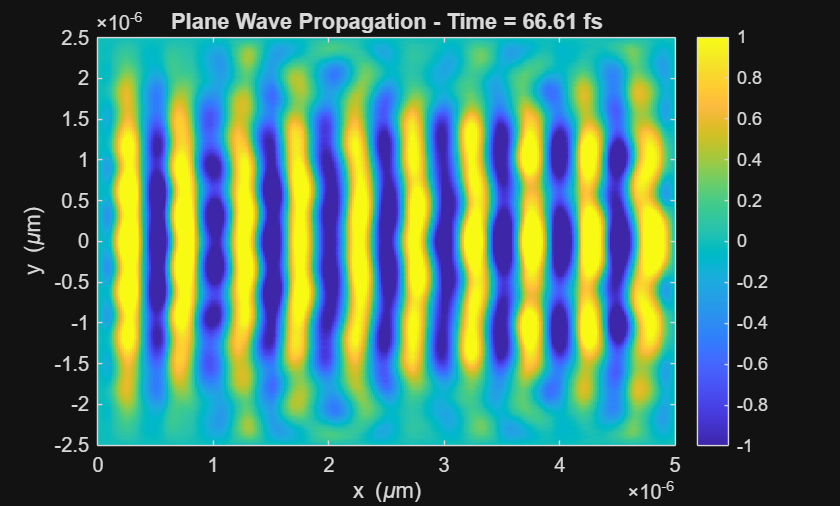

clear all; clc; close all
% Parameters
c = 3e8; % Speed of light in vacuum (m/s)
Lx = 5e-6; Ly = 5e-6; % Dimensions of the 2D domain (meters)
% Lx = 1e-5; Ly = 1e-5; % Dimensions of the 2D domain (meters)
Nx = 300; Ny = 300; % Number of grid points
dx = Lx / (Nx - 1); % Spatial step in x (micrometers)
dy = Ly / (Ny - 1); % Spatial step in y (micrometers)
dt = 0.5 * dx / c; % Time step (CFL condition)
tmax = 4 * Lx / c; % Maximum simulation time
Nt = floor(tmax / dt); % Number of time steps
% Spatial grid
x = linspace(0, Lx, Nx);
y = linspace(-Ly/2, Ly/2, Ny);
% Initialize fields to zero
u = zeros(Ny, Nx); % Field at the current time step
u_prev = zeros(Ny, Nx); % Field at the previous time step
% Light source parameters
lambda = 0.5*10^-6; % Wavelength (meters)
k = 2 * pi / lambda; % Wave number
omega = c * k; % Angular frequency
source_tmax = Lx / c;
source_width = Ly * 3 / 4; % Width of the light source (smaller than Ly)
source_range = (1:Ny);
source_range = source_range((y>min(y)+(Ly-source_width)/2)&(y<max(y)-(Ly-source_width)/2));
% point source array
num_source=50;
source_index_y= round(linspace(min(source_range),max(source_range),num_source));
source_index_x= ones(num_source,1)*round(10);
source_position_x=x(source_index_x);
source_position_y=y(source_index_y);
% Time-stepping loop
for n = 1:Nt
% point source array
if n*dt<source_tmax
for i=1:num_source
point_source = sin(omega*n*dt);
u(source_index_y(i),source_index_x(i))=point_source;
end
end
% Compute Laplacian using central differences
laplacian_u= 4*del2(u,dx,dy);
% Update the field using the 2D wave equation
u_next=2*u- u_prev + (c*dt)^2*laplacian_u;
% Boundary conditions
%u_next = neumann_bc(u_next);
u_next = dirichlet_bc(u_next);
% u_next = absorbing_bc(u_next, u,c, dt, dx, dy);
% Update fields for the next iteration
u_prev=u;
u= u_next;
% Visualization every 5 time steps
if mod(n, 10) == 0
imagesc(x, y, u); % Transpose for correct orientation
axis xy;
xlabel('x (\mum)');
ylabel('y (\mum)');
colorbar;
caxis([-1, 1]); % Adjust color scale
title(['Plane Wave Propagation - Time = ', num2str(n * dt * 1e15, '%.2f'),' fs']);
end
drawnow;
end

%------------------Boundary condition library----------------
%%
%%
function u_next = absorbing_bc(u_next, u, c, dt, dx, dy)
coeffx = (c*dt - dx) / (c*dt + dx);
coeffy = (c*dt - dy) / (c*dt + dy);
% Left (x = 0)
u_next(:,1) = u(:,2) + coeffx * (u_next(:,2) - u(:,1));
% Right (x = Lx)
u_next(:,end) = u(:,end-1) + coeffx * (u_next(:,end-1) - u(:,end));
% Bottom (y = -Ly/2)
u_next(1,:) = u(2,:) + coeffy * (u_next(2,:) - u(1,:));
% Top (y = +Ly/2)
u_next(end,:) = u(end-1,:) + coeffy * (u_next(end-1,:) - u(end,:));
end
function u_next = neumann_bc(u_next)
% Apply Neumann boundary conditions (zero flux)
% Left boundary
u_next(:, 1) = u_next(:, 2); % No gradient at the boundary
% Right boundary
u_next(:, end) = u_next(:, end-1);
% Bottom boundary
u_next(1, :) = u_next(2, :);
% Top boundary
u_next(end, :) = u_next(end-1, :);
end
function u_next = dirichlet_bc(u_next)
% Apply Dirichlet boundary conditions (fixed values)
% Left boundary
u_next(:, 1) = 0; % Set field value to zero at the left boundary
% Right boundary
u_next(:, end) = 0; % Set field value to zero at the right boundary
% Bottom boundary
u_next(1, :) = 0; % Set field value to zero at the bottom boundary
% Top boundary
u_next(end, :) = 0; % Set field value to zero at the top boundary
end